# HW #9

Hayden Carter

Due: 12:06:2019

Linear Circuits

# 1

%1a
fs = 44100;
maxf = fs/2

maxf = 22050

%1b i
F = [15000,22500]./44100;
cheby = Digital("Chebyshev","Low",2, 4, F);
cheby.Filter.order

ans = 1

%1b ii
F = [15000,22500]./44100;
butter = Digital("Butterworth","Low",2, 4, F);
butter.Filter.order

ans = 1

# 2

y[n] + 0.25y[n-1] = 0.5x[n]

H(z) = 0.5 / (1+0.25*z^-1)

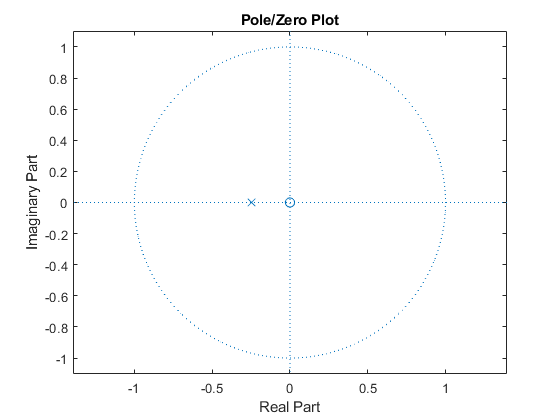

% Plot pole/zero plot
num = 0.5;
den = [1,0.25];
figure(1)
zplane(num,den)
title('Pole/Zero Plot')

h(n) = ((0.25)^n)*u[n]

FIR because as n grows the number aproaches zero.

It is recurisive because of the refrence to a former y values with y[n-1]

Stable: Because the sum of the absolute value of h[n] is less than infinity

s[n] = h[n]  + s[n-1]

# 3

**********************
Section # 1
Numerator coefficients 1 2 1
Denominator coefficients 1 -0.9827 0.66648
______________________
**********************
**********************
Section # 2
Numerator coefficients 1 1 0
Denominator coefficients 1 -0.59771 0
______________________
**********************
K value: 3.4385


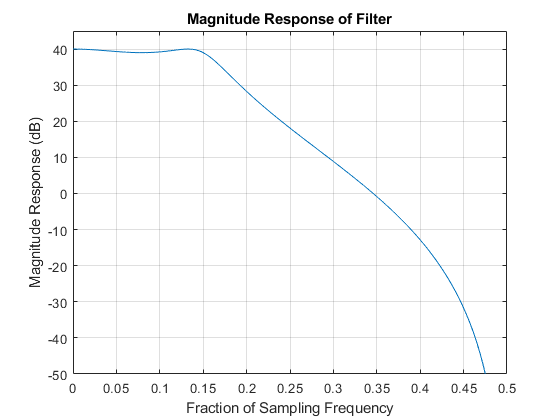

Classification = "Chebyshev";
Type = "Low";
DCGain = 40;
Amax = 1;
Amin = 25;
PassBand = 1500;
StopBand = 3000;
SamplingFreq = 10000;
HWSolver(Classification,Type,DCGain,Amax,Amin,PassBand,StopBand,SamplingFreq)

# 4

**********************
Section # 1
Numerator coefficients 1 -1 0
Denominator coefficients 1 0.47163 0
______________________
**********************
**********************
Section # 2
Numerator coefficients 1 -2 1
Denominator coefficients 1 0.5045 0.61883
______________________
**********************
K value: 7.3597


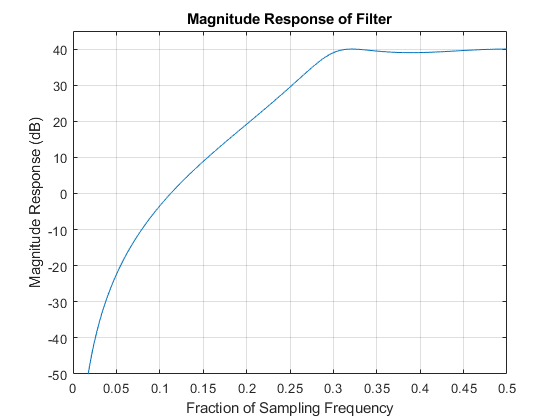

Classification = "Chebyshev";
Type = "High";
DCGain = 40;
Amax = 1;
Amin = 25;
PassBand = 3000;
StopBand = 1500;
SamplingFreq = 10000;
HWSolver(Classification,Type,DCGain,Amax,Amin,PassBand,StopBand,SamplingFreq)

# 5

**********************
Section # 1
Numerator coefficients 1 -1.2246e-16 1
Denominator coefficients 1 -0.39323 0.78035
______________________
**********************
**********************
Section # 2
Numerator coefficients 1 -1.2246e-16 1
Denominator coefficients 1 0.39323 0.78035
______________________
**********************
**********************
Section # 3
Numerator coefficients 1 -1.2246e-16 1
Denominator coefficients 1 -2.2204e-16 0.58806
______________________
**********************
K value: 5.985


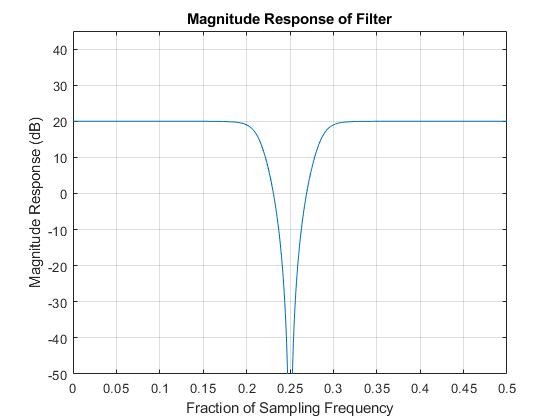

Classification = "Butterworth";
Type = "Notch";
DCGain = 20;
Amax = 1;
Amin = 25;
PassBand = [2000,3000];
StopBand = [2400,2600];
SamplingFreq = 10000;
HWSolver(Classification,Type,DCGain,Amax,Amin,PassBand,StopBand,SamplingFreq)

# 6

Band Coefficient Patern

num = [1 0 -1];

den = [1,-2 * real(obj.zpoles(n)),(abs(obj.zpoles(n))).^2];

The Coeffiencents are not write in the given H(z). 

Lets Graph It!

Graph of given H(z) [Supose to be a Band Pass]

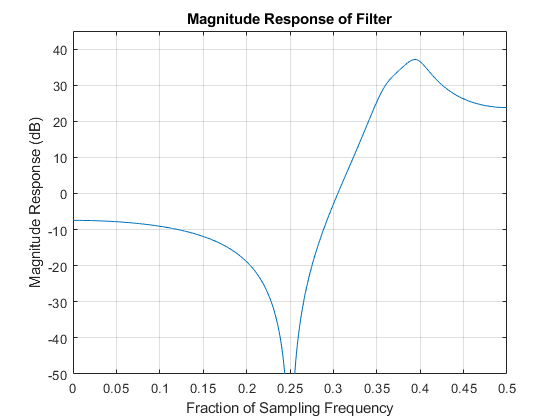

num1 = [1,0,1];
num2 = [1,0,1];
den1 = [1,1.4319,0.8217];
den2 = [1,1.1175,0.7805];
num = conv(num1,num2);
den = conv(den1,den2);
[H,w]=freqz(num,den,4096);
plot(w/2/pi,20*log10(abs(H)))
title('Magnitude Response of Filter')
ylabel('Magnitude Response (dB)')
xlabel('Fraction of Sampling Frequency')
axis([0 0.5 -50 45]);
grid on

Yeah, that H(z) is not correct. Just look at the graph

Also you can look at coef for the num, those arent right either